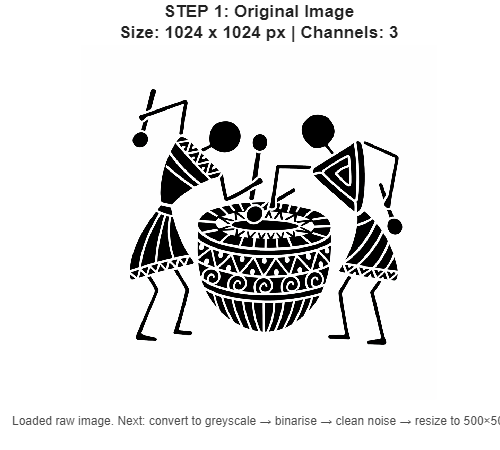

clc; clear; close all;

%% ===== STEP 1: SELECT IMAGE =====
[file, path] = uigetfile({'*.png;*.jpg;*.jpeg'}, 'Select Warli Image');
if isequal(file, 0)
    disp('No file selected'); return;
end
img = imread(fullfile(path, file));

% --- VISUAL: Step 1 Output ---
figure('Name','STEP 1: Original Image','Color','w','Position',[50 500 500 450]);
imshow(img);
title({'STEP 1: Original Image', sprintf('Size: %d x %d px | Channels: %d', size(img,1), size(img,2), size(img,3))}, ...
    'FontSize', 13, 'FontWeight', 'bold');
annotation('textbox',[0.01 0.01 0.98 0.08],'String', ...
    'Loaded raw image. Next: convert to greyscale → binarise → clean noise → resize to 500×500.', ...
    'FitBoxToText','on','EdgeColor','none','FontSize',9,'Color',[0.3 0.3 0.3]);

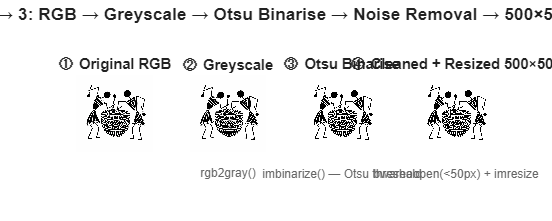



%% ===== STEP 2: CONVERT TO BLACK & WHITE =====
if size(img, 3) == 3
    imgGray = rgb2gray(img);
else
    imgGray = img;
end
mask = imbinarize(imgGray);
mask = bwareaopen(mask, 50);
N    = 500;
mask = imresize(mask, [N N], 'nearest');

% --- VISUAL: Step 2 Output (4-panel progression) ---
figure('Name','STEP 2: Binarisation Pipeline','Color','w','Position',[50 50 1000 400]);
subplot(1,4,1);
imshow(img); title('① Original RGB','FontSize',11,'FontWeight','bold');

subplot(1,4,2);
imshow(imgGray); title('② Greyscale','FontSize',11,'FontWeight','bold');
xlabel('rgb2gray()', 'FontSize', 9, 'Color', [0.4 0.4 0.4]);

subplot(1,4,3);
imshow(imbinarize(imgGray)); title('③ Otsu Binarise','FontSize',11,'FontWeight','bold');
xlabel('imbinarize() — Otsu threshold', 'FontSize', 9, 'Color', [0.4 0.4 0.4]);

subplot(1,4,4);
imshow(mask); title('④ Cleaned + Resized 500×500','FontSize',11,'FontWeight','bold');
xlabel('bwareaopen(<50px) + imresize', 'FontSize', 9, 'Color', [0.4 0.4 0.4]);

sgtitle('STEP 2 → 3: RGB → Greyscale → Otsu Binarise → Noise Removal → 500×500 Mask', ...
    'FontSize', 13, 'FontWeight', 'bold');



%% ===== STEP 3: EXTRACT POINTS =====
[rows, cols] = find(mask);
x = (cols - 1) / (N - 1) * 2 - 1;
y = -((rows - 1) / (N - 1) * 2 - 1);
pts2d = [x, y];
pts2d = unique(pts2d, 'rows');
fprintf('Total points: %d\n', size(pts2d, 1));

Total points: 208828


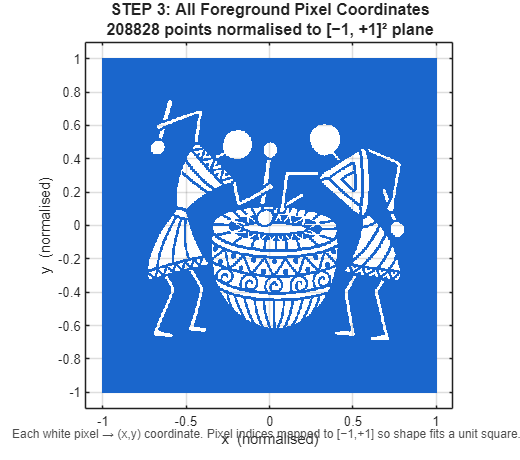


% --- VISUAL: Step 3 Output ---
figure('Name','STEP 3: Extracted 2D Points','Color','w','Position',[580 500 520 460]);
plot(pts2d(:,1), pts2d(:,2), '.', 'Color', [0.1 0.4 0.8], 'MarkerSize', 2);
axis equal; axis([-1.1 1.1 -1.1 1.1]);
grid on; box on;
title({'STEP 3: All Foreground Pixel Coordinates', ...
    sprintf('%d points normalised to [−1, +1]² plane', size(pts2d,1))}, ...
    'FontSize', 12, 'FontWeight', 'bold');
xlabel('x  (normalised)'); ylabel('y  (normalised)');
annotation('textbox',[0.01 0.01 0.98 0.07],'String', ...
    'Each white pixel → (x,y) coordinate. Pixel indices mapped to [−1,+1] so shape fits a unit square.', ...
    'FitBoxToText','on','EdgeColor','none','FontSize',9,'Color',[0.3 0.3 0.3]);



%% ===== STEP 4: DOWNSAMPLE =====
K     = 3;
pts2d = pts2d(1:K:end, :);
fprintf('After downsampling: %d\n', size(pts2d, 1));

After downsampling: 69610


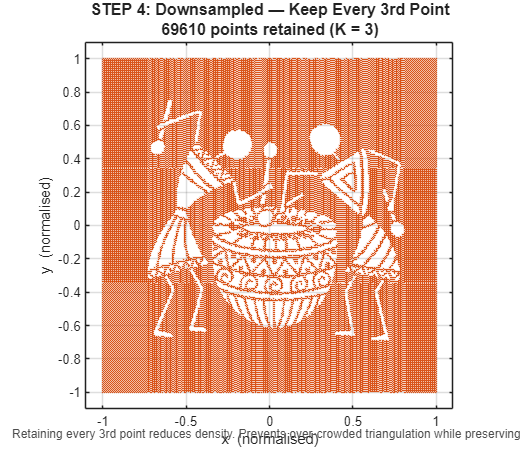


% --- VISUAL: Step 4 Output ---
figure('Name','STEP 4: Downsampled Points','Color','w','Position',[580 50 520 460]);
plot(pts2d(:,1), pts2d(:,2), '.', 'Color', [0.85 0.33 0.1], 'MarkerSize', 3);
axis equal; axis([-1.1 1.1 -1.1 1.1]);
grid on; box on;
title({'STEP 4: Downsampled — Keep Every 3rd Point', ...
    sprintf('%d points retained (K = 3)', size(pts2d,1))}, ...
    'FontSize', 12, 'FontWeight', 'bold');
xlabel('x  (normalised)'); ylabel('y  (normalised)');
annotation('textbox',[0.01 0.01 0.98 0.07],'String', ...
    'Retaining every 3rd point reduces density. Prevents over-crowded triangulation while preserving overall shape topology.', ...
    'FitBoxToText','on','EdgeColor','none','FontSize',9,'Color',[0.3 0.3 0.3]);

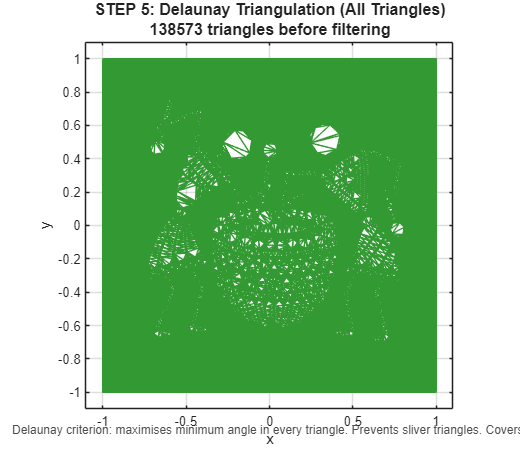



%% ===== STEP 5: TRIANGULATION =====
DT        = delaunayTriangulation(pts2d);
faces_all = DT.ConnectivityList;
pts       = DT.Points;

% --- VISUAL: Step 5 Output (raw DT before filtering) ---
figure('Name','STEP 5: Raw Delaunay Triangulation','Color','w','Position',[1120 500 520 460]);
triplot(DT, 'Color', [0.2 0.6 0.2], 'LineWidth', 0.4);
axis equal; axis([-1.1 1.1 -1.1 1.1]);
grid on; box on;
title({'STEP 5: Delaunay Triangulation (All Triangles)', ...
    sprintf('%d triangles before filtering', size(faces_all,1))}, ...
    'FontSize', 12, 'FontWeight', 'bold');
xlabel('x'); ylabel('y');
annotation('textbox',[0.01 0.01 0.98 0.08],'String', ...
    'Delaunay criterion: maximises minimum angle in every triangle. Prevents sliver triangles. Covers convex hull — gaps appear after filtering.', ...
    'FitBoxToText','on','EdgeColor','none','FontSize',9,'Color',[0.3 0.3 0.3]);



%% ===== STEP 6: REMOVE BAD TRIANGLES =====
cx = (pts(faces_all(:,1),1) + pts(faces_all(:,2),1) + pts(faces_all(:,3),1)) / 3;
cy = (pts(faces_all(:,1),2) + pts(faces_all(:,2),2) + pts(faces_all(:,3),2)) / 3;
cr = round((-cy + 1) / 2 * (N-1) + 1);
cc = round(( cx + 1) / 2 * (N-1) + 1);

valid = cr >= 1 & cr <= N & cc >= 1 & cc <= N;
keep  = false(size(faces_all, 1), 1);
idx   = sub2ind([N N], cr(valid), cc(valid));
keep(valid) = mask(idx);
faces = faces_all(keep, :);

%% ===== STEP 7: REMOVE LONG TRIANGLES =====
p1 = pts(faces(:,1), :);
p2 = pts(faces(:,2), :);
p3 = pts(faces(:,3), :);
e1 = vecnorm(p1-p2, 2, 2);
e2 = vecnorm(p2-p3, 2, 2);
e3 = vecnorm(p3-p1, 2, 2);
faces = faces(max([e1 e2 e3], [], 2) < 0.08, :);
fprintf('Triangles after cleanup: %d\n', size(faces, 1));

Triangles after cleanup: 134229



% --- VISUAL: Steps 6+7 side-by-side comparison ---
figure('Name','STEPS 6–7: Triangle Filtering','Color','w','Position',[1120 50 900 460]);
subplot(1,2,1);
triplot(triangulation(faces_all, pts), 'Color',[0.7 0.1 0.1],'LineWidth',0.3);
axis equal; axis([-1.1 1.1 -1.1 1.1]);
title({'Before Filtering', sprintf('%d triangles (incl. outside + long)', size(faces_all,1))}, ...
    'FontSize', 11, 'FontWeight', 'bold');
xlabel('x'); ylabel('y');

subplot(1,2,2);
triplot(triangulation(faces, pts), 'Color',[0.05 0.5 0.05],'LineWidth',0.5);

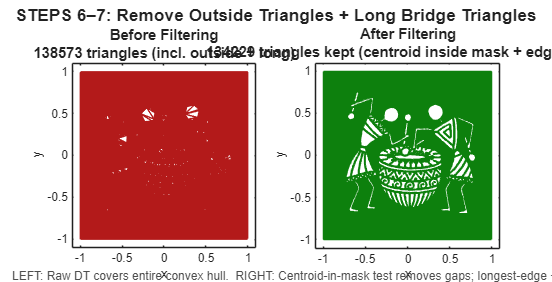

axis equal; axis([-1.1 1.1 -1.1 1.1]);
title({'After Filtering', sprintf('%d triangles kept (centroid inside mask + edge < 0.08)', size(faces,1))}, ...
    'FontSize', 11, 'FontWeight', 'bold');
xlabel('x'); ylabel('y');

sgtitle('STEPS 6–7: Remove Outside Triangles + Long Bridge Triangles', ...
    'FontSize', 13, 'FontWeight', 'bold');
annotation('textbox',[0.01 0.01 0.98 0.05],'String', ...
    'LEFT: Raw DT covers entire convex hull.  RIGHT: Centroid-in-mask test removes gaps; longest-edge < 0.08 removes bridges spanning white space.', ...
    'FitBoxToText','on','EdgeColor','none','FontSize',9,'Color',[0.3 0.3 0.3]);



%% ===== STEP 8: STEREOGRAPHIC PROJECTION =====
scl = 1.2;
X   = pts(:,1) * scl;
Y   = pts(:,2) * scl;
H   = X.^2 + Y.^2;
R   = 50;   % sphere radius in mm

SpherePts = [ ...
    R * 2*X   ./ (H+1), ...
    R * 2*Y   ./ (H+1), ...
    R * (H-1) ./ (H+1) ];

Tri = triangulation(faces, SpherePts);


% --- VISUAL: Step 8 — show flat 2D → sphere side by side + math annotation ---
figure('Name','STEP 8: Stereographic Projection','Color','k','Position',[50 50 1200 520]);

% Left: flat triangulation
ax1 = subplot(1,3,1);
triplot(triangulation(faces, pts), 'Color',[1 0.8 0.4],'LineWidth',0.4);

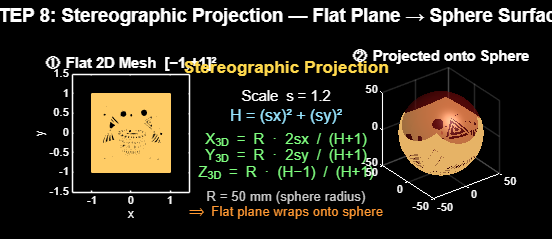

axis equal; axis([-1.5 1.5 -1.5 1.5]);
set(ax1,'Color','k','XColor','w','YColor','w');
title('① Flat 2D Mesh  [−1,+1]²', 'Color','w','FontSize',11,'FontWeight','bold');
xlabel('x','Color','w'); ylabel('y','Color','w');

% Middle: formula card
ax2 = subplot(1,3,2);
axis off;
set(ax2,'Color','k');
text(0.5, 0.90, 'Stereographic Projection', 'Color',[1 0.85 0.3], ...
    'FontSize',13,'FontWeight','bold','HorizontalAlignment','center');
text(0.5, 0.72, 'Scale  s = 1.2', 'Color','w','FontSize',11,'HorizontalAlignment','center');
text(0.5, 0.60, 'H = (sx)² + (sy)²', 'Color',[0.6 0.9 1],'FontSize',12,'HorizontalAlignment','center');
text(0.5, 0.46, 'X_{3D} = R · 2sx / (H+1)', 'Color',[0.5 1 0.5],'FontSize',11,'HorizontalAlignment','center');
text(0.5, 0.36, 'Y_{3D} = R · 2sy / (H+1)', 'Color',[0.5 1 0.5],'FontSize',11,'HorizontalAlignment','center');
text(0.5, 0.26, 'Z_{3D} = R · (H−1) / (H+1)', 'Color',[0.5 1 0.5],'FontSize',11,'HorizontalAlignment','center');
text(0.5, 0.12, 'R = 50 mm (sphere radius)', 'Color',[0.8 0.8 0.8],'FontSize',10,'HorizontalAlignment','center');
text(0.5, 0.03, '⟹  Flat plane wraps onto sphere', 'Color',[1 0.6 0.2],'FontSize',10,'HorizontalAlignment','center');

% Right: 3D sphere
ax3 = subplot(1,3,3);
[sx, sy, sz] = sphere(60);
surf(R*sx, R*sy, R*sz, 'FaceColor',[0.75 0.08 0.08],'EdgeColor','none','FaceAlpha',0.4);
hold on;
patch('Vertices', Tri.Points, 'Faces', Tri.ConnectivityList, ...
    'FaceColor',[1 0.96 0.88],'EdgeColor',[0.9 0.7 0.4],'LineWidth',0.3);
axis equal; view(3);
set(ax3,'Color','k','XColor','w','YColor','w','ZColor','w');
lighting gouraud; camlight;
title('② Projected onto Sphere', 'Color','w','FontSize',11,'FontWeight','bold');

sgtitle('STEP 8: Stereographic Projection — Flat Plane → Sphere Surface', ...
    'Color','w','FontSize',14,'FontWeight','bold');

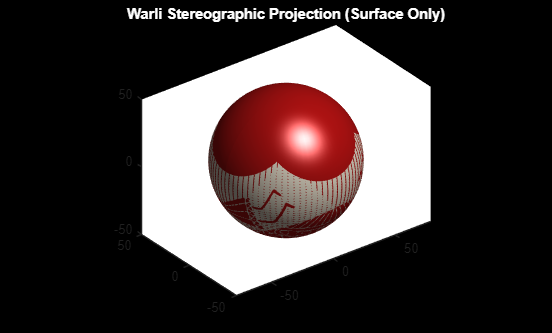



%% ===== STEP 9: VISUALIZE SURFACE MESH =====
figure('Color','k'); hold on;
[sx, sy, sz] = sphere(80);
surf(R*sx, R*sy, R*sz, ...
    'FaceColor', [0.75 0.08 0.08], ...
    'EdgeColor', 'none');
patch('Vertices', Tri.Points, 'Faces', Tri.ConnectivityList, ...
    'FaceColor', [1 0.96 0.88], ...
    'EdgeColor', 'none');
axis equal; view(3);
lighting gouraud; camlight;
title('Warli Stereographic Projection (Surface Only)', 'Color', 'w');



%% ===== STEP 9.5: ADD THICKNESS =====
thickness = 3.0;
outerPts  = Tri.Points;
outerFace = Tri.ConnectivityList;
nOuter    = size(outerPts, 1);

ptNorms = outerPts ./ vecnorm(outerPts, 2, 2);
innerPts  = outerPts - thickness * ptNorms;
innerFace = outerFace(:, [1 3 2]);

allEdges        = [outerFace(:,[1 2]); outerFace(:,[2 3]); outerFace(:,[3 1])];
allEdges_sorted = sort(allEdges, 2);
[~, ia, ic]     = unique(allEdges_sorted, 'rows');
edgeCounts      = accumarray(ic, 1);
isBoundary      = edgeCounts == 1;
boundaryEdges   = allEdges(ia(isBoundary), :);
fprintf('Boundary edges found: %d\n', size(boundaryEdges, 1));

Boundary edges found: 5423



nEdges    = size(boundaryEdges, 1);
sideWalls = zeros(nEdges * 2, 3);
for ei = 1:nEdges
    a = boundaryEdges(ei, 1);
    b = boundaryEdges(ei, 2);
    c = a + nOuter;
    d = b + nOuter;
    sideWalls(2*ei-1, :) = [a, d, b];
    sideWalls(2*ei,   :) = [a, c, d];
end

allPts   = [outerPts; innerPts];
allFaces = [outerFace; innerFace + nOuter; sideWalls];
SolidTri = triangulation(allFaces, allPts);

fprintf('Solid mesh: %d vertices, %d faces\n', size(allPts,1), size(allFaces,1));

Solid mesh: 139220 vertices, 279304 faces


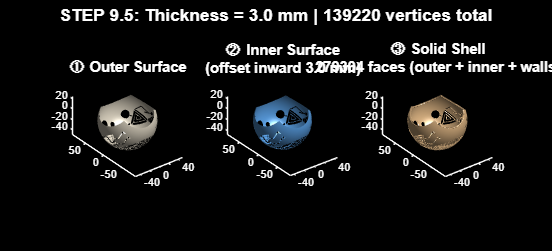


% --- VISUAL: Step 9.5 — Thickness exploded diagram ---
figure('Name','STEP 9.5: Thickness Addition','Color','k','Position',[50 50 1100 500]);

subplot(1,3,1);
patch('Vertices', outerPts, 'Faces', outerFace, ...
    'FaceColor',[1 0.96 0.88],'EdgeColor','none');
axis equal; view(3); lighting gouraud; camlight;
set(gca,'Color','k','XColor','w','YColor','w','ZColor','w');
title('① Outer Surface','Color','w','FontSize',11,'FontWeight','bold');

subplot(1,3,2);
patch('Vertices', innerPts, 'Faces', innerFace, ...
    'FaceColor',[0.4 0.7 1],'EdgeColor','none');
axis equal; view(3); lighting gouraud; camlight;
set(gca,'Color','k','XColor','w','YColor','w','ZColor','w');
title({'② Inner Surface', sprintf('(offset inward %.1f mm)', thickness)}, ...
    'Color','w','FontSize',11,'FontWeight','bold');

subplot(1,3,3);
patch('Vertices', SolidTri.Points, 'Faces', SolidTri.ConnectivityList, ...
    'FaceColor',[1 0.82 0.6],'EdgeColor','none');
axis equal; view(3); lighting gouraud; camlight;
set(gca,'Color','k','XColor','w','YColor','w','ZColor','w');
title({'③ Solid Shell', sprintf('%d faces (outer + inner + walls)', size(allFaces,1))}, ...
    'Color','w','FontSize',11,'FontWeight','bold');

sgtitle(sprintf('STEP 9.5: Thickness = %.1f mm | %d vertices total', thickness, size(allPts,1)), ...
    'Color','w','FontSize',13,'FontWeight','bold');

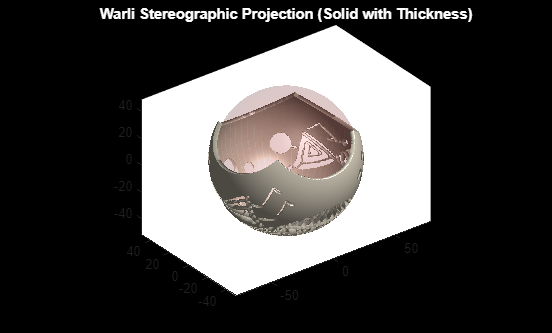



%% ===== STEP 9.6: VISUALIZE SOLID MESH =====
figure('Color','k'); hold on;
[sx, sy, sz] = sphere(60);
surf((R - thickness)*sx, (R - thickness)*sy, (R - thickness)*sz, ...
    'FaceColor', [0.75 0.08 0.08], ...
    'EdgeColor', 'none', 'FaceAlpha', 0.12);
patch('Vertices', SolidTri.Points, 'Faces', SolidTri.ConnectivityList, ...
    'FaceColor', [1 0.96 0.88], ...
    'EdgeColor', 'none');
axis equal; view(3);
lighting gouraud; camlight;
title('Warli Stereographic Projection (Solid with Thickness)', 'Color', 'w');

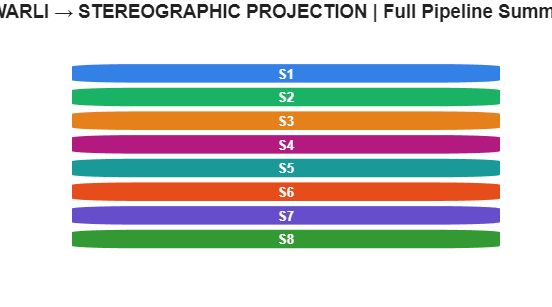


% --- VISUAL: Final Summary Panel ---
figure('Name','PIPELINE SUMMARY','Color','w','Position',[200 100 900 500]);
axis off;
steps = { ...
    'S1', 'Image Acquisition',        'RGB loaded, Otsu threshold, noise < 50px removed, resized 500×500'; ...
    'S2', 'Point Extraction',         sprintf('White pixels → (x,y) in [−1,+1]² — Total: %d pts', size(pts,1)); ...
    'S3', 'Downsampling K=3',         sprintf('Every 3rd point kept → %d points', size(pts2d,1)); ...
    'S4', 'Delaunay Triangulation',   sprintf('%d triangles (raw, before filtering)', size(faces_all,1)); ...
    'S5', 'Triangle Filtering',       sprintf('%d triangles kept (centroid inside + edge < 0.08)', size(faces,1)); ...
    'S6', 'Stereographic Projection', sprintf('Flat plane → Sphere R=%d mm, scale=1.2', R); ...
    'S7', 'Thickness Addition',       sprintf('Outer − inner − sidewalls | t=%.1f mm', thickness); ...
    'S8', 'OBJ Export',               sprintf('Solid mesh: %d vertices, %d faces', size(allPts,1), size(allFaces,1)); ...
};
colors = [0.2 0.5 0.9; 0.1 0.7 0.4; 0.9 0.5 0.1; 0.7 0.1 0.5; ...
          0.1 0.6 0.6; 0.9 0.3 0.1; 0.4 0.3 0.8; 0.2 0.6 0.2];
for i = 1:size(steps,1)
    ypos = 0.93 - (i-1)*0.115;
    rectangle('Position',[0.02 ypos-0.005 0.08 0.09], ...
        'FaceColor', colors(i,:), 'Curvature', 0.3, 'EdgeColor','none');
    text(0.06, ypos+0.038, steps{i,1}, 'FontSize',10,'FontWeight','bold', ...
        'Color','w','HorizontalAlignment','center');
    text(0.13, ypos+0.052, steps{i,2}, 'FontSize',10,'FontWeight','bold','Color', colors(i,:));
    text(0.13, ypos+0.018, steps{i,3}, 'FontSize', 9, 'Color',[0.3 0.3 0.3]);
end
title('WARLI → STEREOGRAPHIC PROJECTION | Full Pipeline Summary', ...
    'FontSize',14,'FontWeight','bold');



%% ===== STEP 10: EXPORT SOLID MESH TO OBJ =====
[file, path] = uiputfile('warli_solid.obj', 'Save Solid OBJ File');
if isequal(file, 0)
    disp('User cancelled saving'); return;
end
filename = fullfile(path, file);
fid = fopen(filename, 'w');
if fid == -1
    error('Cannot open file for writing. Try a different location.');
end
fprintf(fid, '# Warli Solid Mesh — outer + inner + sidewalls\n');
fprintf(fid, '# Sphere radius: %g mm  |  Thickness: %g mm\n', R, thickness);
for i = 1:size(SolidTri.Points, 1)
    fprintf(fid, 'v %f %f %f\n', ...
        SolidTri.Points(i,1), SolidTri.Points(i,2), SolidTri.Points(i,3));
end
for i = 1:size(SolidTri.ConnectivityList, 1)
    fprintf(fid, 'f %d %d %d\n', ...
        SolidTri.ConnectivityList(i,1), ...
        SolidTri.ConnectivityList(i,2), ...
        SolidTri.ConnectivityList(i,3));
end
fclose(fid);
disp(['Solid OBJ saved at: ', filename]);

Solid OBJ saved at: C:\Users\MY HOME\Downloads\Ashritha_CS23B2001_MFD_Assignment1.obj
